DTLZ3 Test function of Deb et a. 2001

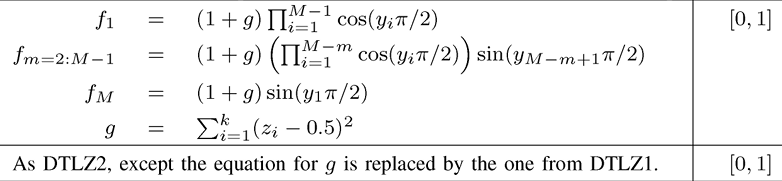

[https://tik-old.ee.ethz.ch/file//3ec604450bf683daaf27f9027e69f44d/DTLZ2004a.pdf](https://tik-old.ee.ethz.ch/file//3ec604450bf683daaf27f9027e69f44d/DTLZ2004a.pdf)

function Fx = AMALGAM_DTLZ3(x,M)
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %
%AMALGAM_DTLZ3: DTZL3 m-variate test function of Deb et al. 2001          %
%                                                                         %
%  SYNOPSIS                                                               %
%   Fx = AMALGAM_DTZL3(x,m)                                               %
%  where                                                                  %
%   x       [input] 1xd parameter vector                                  %
%   m       [input] # objective functions                                 %
%   Fx      [outpt] m objective function values                           %
%                                                                         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %
%                                                                         %
% DTZL3 example from the following paper                                  %
%  Deb, K., L. Thiele, M. Laumanns, and E. Zitzler (2001), Scalable Test  %
%      Problems for Evolutionary Multi-Objective Optimization. Kanpur,    %
%      India: Kanpur Genetic Algorithms Lab. (KanGAL), Indian Institute   %
%      of Technology, KanGAL Report 2001001                               % 
%      https://tik-old.ee.ethz.ch/file// ...                              %
%          3ec604450bf683daaf27f9027e69f44d/DTLZ2004a.pdf                 %
%                                                                         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %
%                                                                         %
%  © Written by Jasper A. Vrugt, Jan. 2005                                %
%  Los Alamos National Laboratory                                         %
%  University of California Irvine                                        %
%                                                                         %
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %

Fx = nan(M,1);                                      % # objectives
d = numel(x);                                       % # parameters
k = d - M + 1;                                      % integer k 
xM = x(d-k+1:d);                                    % Last k variables: xM  
xnotM = x(1:d-k);                                   % Remaining parameters 
k1 = d - k;
g = 100 * (k + sum( (xM - .5).^2 ...                % g(xM)
    - cos(20*pi*(xM - .5))));                
Fx(1) = (1 + g) * prod(cos(xnotM(1:k1)*pi/2)); % f_1(x)
for m = 2:M - 1
    Fx(m) = (1 + g) * ...                           % f_m(x)
        prod(cos(xnotM(1:k1-m+1)*pi/2))*sin(xnotM(k1-m+2)*pi/2);
end
Fx(M) = (1 + g) * sin(xnotM(1)*pi/2);               % f_M(x)

end